# 方位混叠与多普勒中心

由于传感器与目标的相对运动，接收信号经历了多普勒频移。**这一多普勒频移存在于解调后的接收信号中**，与脉冲带宽相比，频移很小，难以察觉，但是，当沿着方位向观测时，多普勒频移就很明显了，这是方位向调制与方位处理的基础。       

**接收信号：**$s_r(\tau,\eta)=A_0\omega_r(\tau-2R(\eta)/c)\omega_a(\eta-\eta_c)\exp\{-j4\pi f_0R(\eta)/c\}\exp\{j\pi K_r(\tau-2R(\eta)/c)^2\}$

                              在低斜情况下使用瞬时斜距使用抛物线近似：$R(\eta)=R_0+v_r^2\eta^2/2R_0$

                              
$$=A_0\omega_r(\tau-2R(\eta)/c)\omega_a(\eta-\eta_c)\exp\{-j4\pi R_0/\lambda\}\exp\{-j\pi K_a \eta^2\}\exp\{j\pi K_r(\tau-2R(\eta)/c)^2\}$$


**低斜情况下的信号频谱**

**距离多普勒频谱：**$S_{rd}(\tau,f_\eta)\approx\omega_r(\tau-2R_{rd}(f_\eta)/c)W_a(f_\eta-f_{\eta_c})\exp\{j\theta_{rd}\}$

**           二维频谱：**$S_{df}(f_\tau,f_\eta)\approx W_r(f_\tau)W_a(f_\eta-f_{\eta_c})\exp\{j\theta_{df}\}$ 

**一般情况下的信号频谱**

**           二维频谱：**$S_{df}(f_\tau,f_\eta)\approx W_r(f_\tau)W_a(f_\eta-f_{\eta_c})\exp\{j\theta_r(f_\tau,f_\eta)\}$

**距离多普勒频谱：**$S_{rd}(\tau,f_\eta)\approx\omega_r([1/(1-K_rZ)][\tau-2R_0/cD(f_\eta,V_r)])W_a(f_\eta-f_{\eta_c})\exp\{j\theta_a(\tau,f_\eta)\}$

### 方位混叠和模糊的起因

**方位混叠的起因**

距离信号起初是连续时间信号，经过正交解调后变成基带信号，然后被模数转换器采样变为离散时间信号。而方位信号从一开始就是离散时间信号，其固有的采样频率为PRF。

方位采样率PRF的提高常常受到诸如距离测绘带等因素的限制，为了避免距离模糊，PRF必须足够低。然而，雷达系统只能观测到$[-PRF/2,PRF/2]$范围内的频率，或者$[0,PRF]$范围内的频率(这取决于对数字频域的解释)，这意味着超出范围频率分量将会混叠进$[-PRF/2,PRF/2]$里，从而引起方位混叠。

**方位模糊的起因**

对于方位向线性调频信号而言，其方位混叠在时域表现为方位信号波形发生自我重复，又因为匹配滤波器按相同的相位形式对方位信号的每一混叠部分进行处理，最终会使压缩后的数据中出现鬼影目标，从而引起方位模糊。

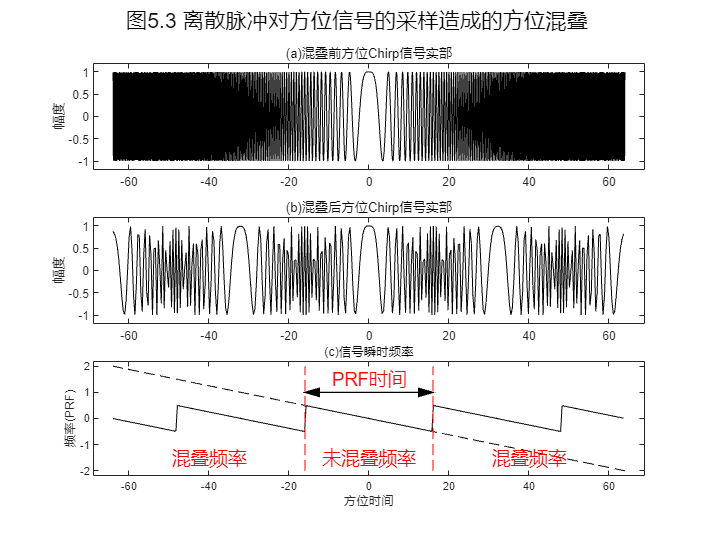

clc
clear
close all
% 已知参数
Ta = 128;                      % 脉冲持续时间
Ka = -0.085;                   % 方位向调频率
% 参数计算
Delta_f_dop = abs(Ka*Ta);      % 方位信号带宽
% 参数设置
alpha_as = [5,.25];           % 方位过采样率
Fa1 = alpha_as(1)*Delta_f_dop; % 方位采样频率PRF
N1 = 2*ceil(Fa1*Ta/2);         % 方位采样点数
dt1 = Ta/N1;                   % 采样时间间隔
df1 = Fa1/N1;                  % 采样频率间隔
Fa2 = alpha_as(2)*Delta_f_dop; % 方位采样频率PRF
N2 = 2*ceil(Fa2*Ta/2) ;        % 方位采样点数
dt2 = Ta/N2;                   % 采样时间间隔
df2 = Fa2/N2;                  % 采样频率间隔
% 变量设置
t1 = -Ta/2:dt1:Ta/2-dt1;       % 时间变量
t2 = -Ta/2:dt2:Ta/2-dt2;       % 时间变量
f1 = -Fa1/2:df1:Fa1/2-df1;     % 频率变量
f1 = -Fa2/2:df2:Fa2/2-df2;     % 频率变量
% 信号表达
st1 = exp(1j*pi*Ka*t1.^2);     % Chirp信号复数表达式
st2 = exp(1j*pi*Ka*t2.^2);     % Chirp信号复数表达式
% 参数计算
F1 = Ka*t1/Fa2;
F2 = (Ka*t2+floor((Fa2/2-Ka*t2)/Fa2)*Fa2)/Fa2;
% 绘图
H = figure();
set(H,'position',[100,100,800,600]);
subplot(311),plot(t1,real(st1),'k')
axis([-Ta/2-5 Ta/2+5,-1.2 1.2])
title('(a)混叠前方位Chirp信号实部'),ylabel('幅度')
subplot(312),plot(t2,real(st2),'k')
axis([-Ta/2-5 Ta/2+5,-1.2 1.2])
title('(b)混叠后方位Chirp信号实部'),ylabel('幅度')
subplot(313),plot(t1,F1,'K--',t2,F2,'K')
axis([-Ta/2-5 Ta/2+5,-2.2 2.2])
title('(c)信号瞬时频率'),xlabel('方位时间'),ylabel('频率(PRF)')
arrow([-16,1],[+16,1],'Color','k','Linewidth',1);
arrow([+16,1],[-16,1],'Color','k','Linewidth',1);
text(0,+1.5,'PRF时间','FontSize',14,'Color','red','HorizontalAlignment','center')
line([-16,-16],[-2,+2],'Color','r','LineStyle','--')
line([+16,+16],[-2,+2],'Color','r','LineStyle','--')
text(0,-1.5,'未混叠频率','FontSize',14,'Color','r','HorizontalAlignment','center')
text(-40,-1.5,'混叠频率','FontSize',14,'Color','r','HorizontalAlignment','center')
text(+40,-1.5,'混叠频率','FontSize',14,'Color','r','HorizontalAlignment','center')
sgtitle('图5.3 离散脉冲对方位信号的采样造成的方位混叠','Fontsize',16,'color','k')

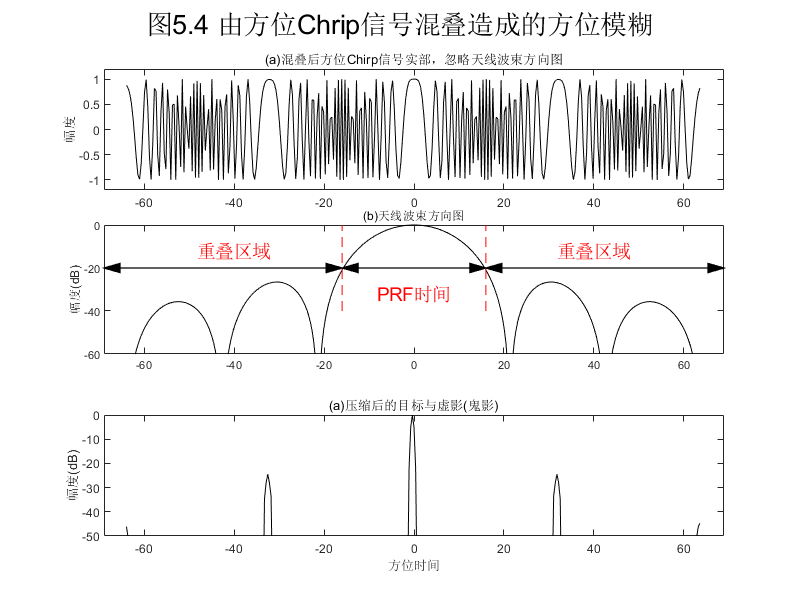

clc
clear
close all
% 已知参数
Ta = 128;                      % 脉冲持续时间
Ka = -0.085;                   % 方位向调频率
% 参数计算
Delta_f_dop = abs(Ka*Ta);      % 方位信号带宽
% 参数设置
alpha_as = [5,0.25];           % 方位过采样率
Fa1 = alpha_as(1)*Delta_f_dop; % 方位采样频率PRF
N1 = 2*ceil(Fa1*Ta/2);         % 方位采样点数
dt1 = Ta/N1;                   % 采样时间间隔
df1 = Fa1/N1;                  % 采样频率间隔
Fa2 = alpha_as(2)*Delta_f_dop; % 方位采样频率PRF
N2 = 2*ceil(Fa2*Ta/2);         % 方位采样点数
dt2 = Ta/N2;                   % 采样时间间隔
df2 = Fa2/N2;                  % 采样频率间隔
% 变量设置
t1 = -Ta/2:dt1:Ta/2-dt1;       % 时间变量
t2 = -Ta/2:dt2:Ta/2-dt2;       % 时间变量
f1 = -Fa1/2:df1:Fa1/2-df1;     % 频率变量
f1 = -Fa2/2:df2:Fa2/2-df2;     % 频率变量
% 信号表达
st1 = exp(1j*pi*Ka*t1.^2);     % 方位Chirp信号
st2 = exp(1j*pi*Ka*t2.^2);     % 方位Chirp信号
omega_a = sinc(6*t2/Ta).^2;    % 双程天线波束方向图
st  = omega_a.*st2;            % 天线方向图调制的方位Chirp信号
omega_a_nor = abs(omega_a)./max(abs(omega_a));      % 归一化
omega_a_log = 20*log10(omega_a_nor);                % 对数化
% 窗函数
window_1 = kaiser(N2,2.5)';                         % 时域窗
Window_1 = fftshift(window_1);                      % 频域窗
% 信号变换-->方式一
ht_1 = conj(fliplr(st));                            % 将时间反褶后的复制脉冲取复共轭
ht_window_1 = window_1.*ht_1;                       % 加窗
Hf_1 = fftshift(fft(ht_window_1,N2));               % 计算补零离散傅里叶变换
% 窗函数
window_2 = kaiser(N2,2.5)';                         % 时域窗
Window_2 = fftshift(window_2);                      % 频域窗
% 信号变换-->方式二
ht_2 = st;                                          % 复制信号
ht_window_2 = window_2.*ht_2;                       % 加窗
Hf_2 = fftshift(conj(fft(ht_window_2,N2)));         % 计算补零离散傅里叶变换
% 窗函数
window_3 = kaiser(N2,2.5)';                         % 时域窗
Window_3 = fftshift(window_3);                      % 频域窗
% 信号变换-->方式三
Hf_3 = exp(1j*pi*f1.^2/Ka);                         % 计算补零离散傅里叶变换
% 信号表达
Sf = fftshift(fft(st));
Sf_1 = Sf.*Hf_1;
st_1 = ifft(ifftshift(Sf_1));                       % 方式一匹配滤波结果
st_1_nor = abs(st_1)./max(abs(st_1));               % 归一化
st_1_log = 20*log10(st_1_nor);                      % 对数化
Sf_2 = Sf.*Hf_2;
st_2 = ifft(ifftshift(Sf_2));                       % 方式二匹配滤波结果
st_2_nor = abs(st_2)./max(abs(st_2));               % 归一化
st_2_log = 20*log10(st_2_nor);                      % 对数化
Sf_3 = Sf.*Hf_3;
st_3 = ifft(ifftshift(Sf_3));                       % 方式三匹配滤波结果
st_3_nor = abs(st_3)./max(abs(st_3));               % 归一化
st_3_log = 20*log10(st_3_nor);                      % 对数化
% 绘图
H = figure();
set(H,'position',[100,100,800,600]);
subplot(311),plot(t2,real(st2),'k')
axis([-Ta/2-5 Ta/2+5,-1.2 1.2])
title('(a)混叠后方位Chirp信号实部，忽略天线波束方向图'),ylabel('幅度')
subplot(312),plot(t2,omega_a_log,'k')
axis([-Ta/2-5 Ta/2+5,-60 0])
title('(b)天线波束方向图'),ylabel('幅度(dB)')
line([-16,-16],[-40,0],'Color','r','LineStyle','--')
line([+16,+16],[-40,0],'Color','r','LineStyle','--')
arrow([-16,-20],[+16,-20],'Color','k','Linewidth',1);
arrow([+16,-20],[-16,-20],'Color','k','Linewidth',1);
arrow([-69,-20],[-16,-20],'Color','k','Linewidth',1);
arrow([-16,-20],[-69,-20],'Color','k','Linewidth',1);
arrow([+16,-20],[+69,-20],'Color','k','Linewidth',1);
arrow([+69,-20],[+16,-20],'Color','k','Linewidth',1);
text(0,-32,'PRF时间','FontSize',14,'Color','red','HorizontalAlignment','center')
text(-40,-12,'重叠区域','FontSize',14,'Color','red','HorizontalAlignment','center')
text(+40,-12,'重叠区域','FontSize',14,'Color','red','HorizontalAlignment','center')
subplot(313),plot(t2,fftshift(st_1_log),'k')
axis([-Ta/2-5 Ta/2+5,-50 0])
title('(a)压缩后的目标与虚影(鬼影)'),xlabel('方位时间'),ylabel('幅度(dB)')
sgtitle('图5.4 由方位Chrip信号混叠造成的方位模糊','Fontsize',20,'color','k')

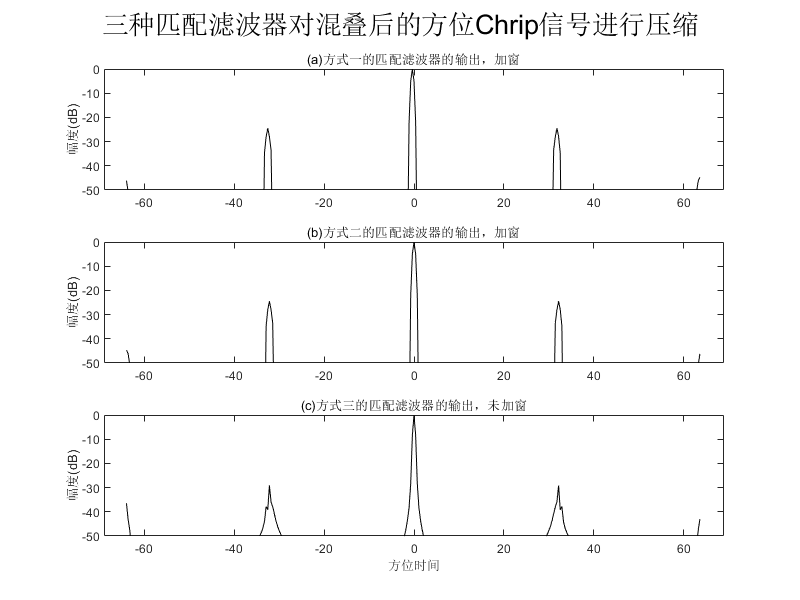

% 绘图
G = figure();
set(G,'position',[100,100,800,600]);
subplot(311),plot(t2,fftshift(st_1_log),'k')
axis([-Ta/2-5 Ta/2+5,-50 0])
title('(a)方式一的匹配滤波器的输出，加窗'),ylabel('幅度(dB)')
subplot(312),plot(t2,fftshift(st_2_log),'k')
axis([-Ta/2-5 Ta/2+5,-50 0])
title('(b)方式二的匹配滤波器的输出，加窗'),ylabel('幅度(dB)')
subplot(313),plot(t2,st_3_log,'k')
axis([-Ta/2-5 Ta/2+5,-50 0])
title('(c)方式三的匹配滤波器的输出，未加窗'),xlabel('方位时间'),ylabel('幅度(dB)')
sgtitle('三种匹配滤波器对混叠后的方位Chrip信号进行压缩','Fontsize',20,'color','k')

### 多普勒中心

点目标接收信号能量只集中在一个PRF时间$\Delta\eta_{PRF}$，信号幅度受到方位向波束形状的调制，这种调制使峰值出现在某一频率点上。由于沿波束中心或瞄准线方向上的波束增益最大，峰值调制出现在波束中心穿越时刻$\eta_{c}$，此时的多普乐频率为数据方位中心频率，称为**“多普勒中心”**。

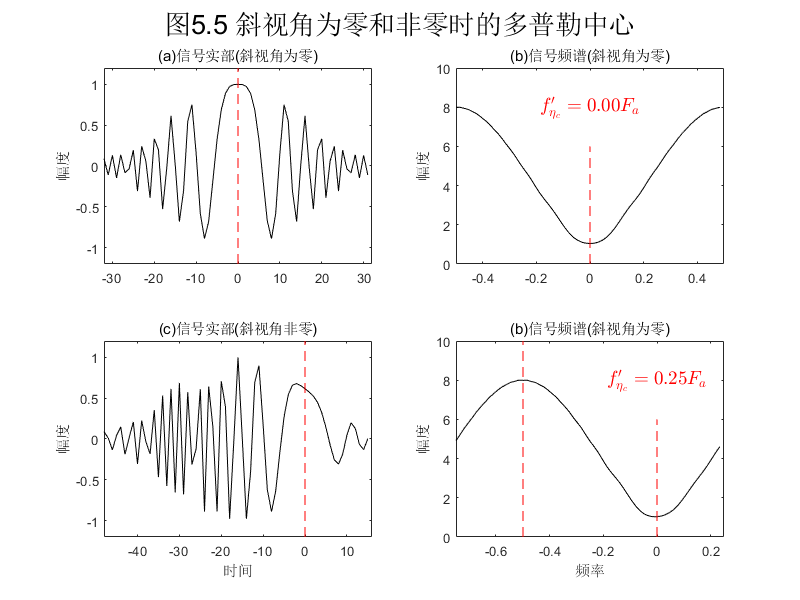

clc
clear
close all
% 已知参数                           
Ta = 64;                        % 脉冲持续时间
Ka = -1.56e-2;                  % 方位向调频率
% 参数计算
Delta_f_dop = abs(Ka*Ta);       % 方位信号带宽
% 参数设置
alpha_as = 1;                   % 方位过采样率
Fa = alpha_as*Delta_f_dop;      % 方位采样频率PRF
N = 2*ceil(Fa*Ta/2);            % 方位采样点数
dt = Ta/N;                      % 采样时间间隔
df = Fa/N;                      % 采样频率间隔
% 变量设置
t1 = -Ta/2:dt:Ta/2-dt;          % 时间变量
f1 = -Fa/2:df:Fa/2-df;          % 频率变量
t2 = -3*Ta/4:dt:Ta/4-dt;        % 时间变量
f2 = -3*Fa/4:df:Fa/4-df;        % 频率变量
n = 0:N-1;                      % 采样变量
% 信号表达
st1 = exp(1j*pi*Ka*t1.^2);      % 方位Chirp信号
st2 = exp(1j*pi*Ka*t2.^2);      % 方位Chirp信号
omega_a = sinc(1.5*t1/Ta).^2;   % 双程天线波束方向图
omega_a_nor = abs(omega_a)./max(abs(omega_a));      % 归一化
omega_a_log = 20*log10(omega_a_nor);                % 对数化
st1 = omega_a.*st1;             % 天线方向图调制的方位Chirp信号
st2 = omega_a.*st2;             % 天线方向图调制的方位Chirp信号
% 信号表达                    
Sf1 = fft(st1);                 % Chirp信号频谱表达式
Sf2 = fft(st2);                 % Chirp信号频谱表达式
% 绘图
H = figure();
set(H,'position',[100,100,800,600]);
subplot(221),plot(t1,real(st1),'k')
axis([-Ta/2 Ta/2,-1.2 1.2])
title('(a)信号实部(斜视角为零)'),ylabel('幅度')
line([0,0],[-1.2,1.2],'Color','r','LineStyle','--')
subplot(222),plot(f1,abs(Sf1),'k')
axis([-Fa/2 Fa/2,0 10])
title('(b)信号频谱(斜视角为零)'),ylabel('幅度')
line([0,0],[0,6],'Color','r','LineStyle','--')
text(0,8,'$$f_{\eta_c}^{\prime}=0.00F_a$$','Interpreter','latex','FontSize',14,'Color','red','HorizontalAlignment','center')
subplot(223),plot(t2,real(st2),'k')
axis([-Ta/2-Ta/4 Ta/2-Ta/4,-1.2 1.2])
title('(c)信号实部(斜视角非零)'),xlabel('时间'),ylabel('幅度')
line([0,0],[-1.2,1.2],'Color','r','LineStyle','--')
subplot(224),plot(f2,abs(Sf2),'k')
axis([-Fa/2-Fa/4 Fa/2-Fa/4,0 10])
title('(b)信号频谱(斜视角为零)'),xlabel('频率'),ylabel('幅度')
line([0,0],[0,6],'Color','r','LineStyle','--')
line([-Fa/2,-Fa/2],[0,10],'Color','r','LineStyle','--')
text(0,8,'$$f_{\eta_c}^{\prime}=0.25F_a$$','Interpreter','latex','FontSize',14,'Color','red','HorizontalAlignment','center')
sgtitle('图5.5 斜视角为零和非零时的多普勒中心','Fontsize',20,'color','k')

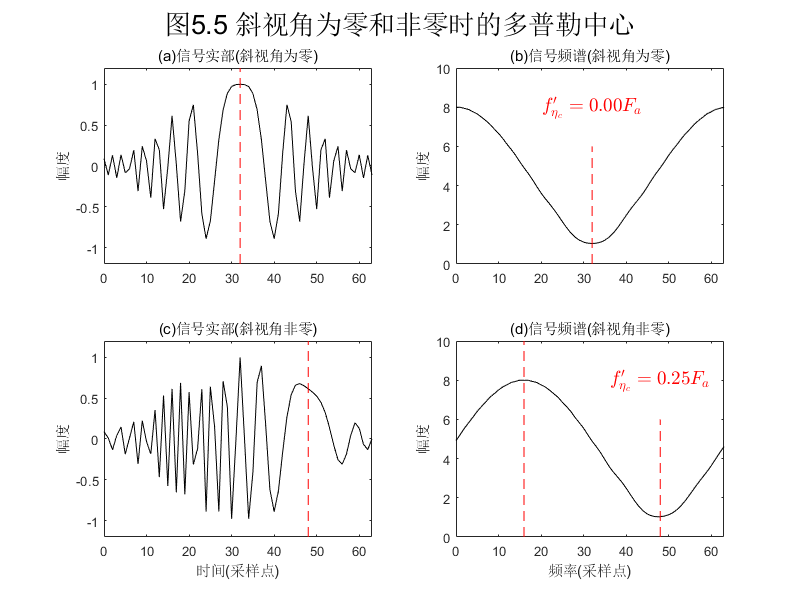

% 绘图
G = figure();
set(G,'position',[100,100,800,600]);
subplot(221),plot(n,real(st1),'k')
axis([0 N-1,-1.2 1.2])
title('(a)信号实部(斜视角为零)'),ylabel('幅度')
line([32,32],[-1.2,1.2],'Color','r','LineStyle','--')
subplot(222),plot(n,abs(Sf1),'k')
axis([0 N-1,0 10])
title('(b)信号频谱(斜视角为零)'),ylabel('幅度')
line([32,32],[0,6],'Color','r','LineStyle','--')
text(32,8,'$$f_{\eta_c}^{\prime}=0.00F_a$$','Interpreter','latex','FontSize',14,'Color','red','HorizontalAlignment','center')
subplot(223),plot(n,real(st2),'k')
axis([0 N-1,-1.2 1.2])
title('(c)信号实部(斜视角非零)'),xlabel('时间(采样点)'),ylabel('幅度')
line([48,48],[-1.2 1.2],'Color','r','LineStyle','--')
subplot(224),plot(n,abs(Sf2),'k')
axis([0 N-1,0 10])
title('(d)信号频谱(斜视角非零)'),xlabel('频率(采样点)'),ylabel('幅度')
line([48,48],[0,6],'Color','r','LineStyle','--')
line([16,16],[0,10],'Color','r','LineStyle','--')
text(48,8,'$$f_{\eta_c}^{\prime}=0.25F_a$$','Interpreter','latex','FontSize',14,'Color','red','HorizontalAlignment','center')
sgtitle('图5.5 斜视角为零和非零时的多普勒中心','Fontsize',20,'color','k')

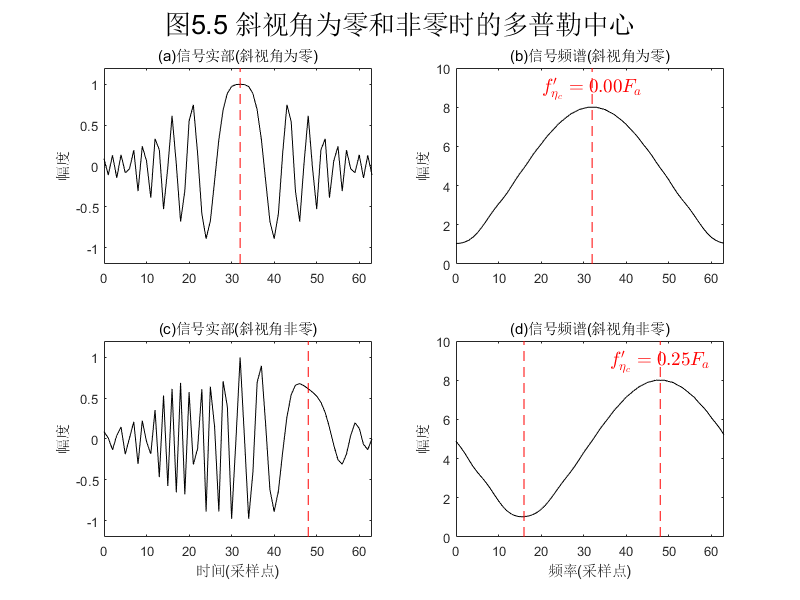

% 绘图
G = figure();
set(G,'position',[100,100,800,600]);
subplot(221),plot(n,real(st1),'k')
axis([0 N-1,-1.2 1.2])
title('(a)信号实部(斜视角为零)'),ylabel('幅度')
line([32,32],[-1.2,1.2],'Color','r','LineStyle','--')
subplot(222),plot(n,abs(fftshift(Sf1)),'k')
axis([0 N-1,0 10])
title('(b)信号频谱(斜视角为零)'),ylabel('幅度')
line([32,32],[0,10],'Color','r','LineStyle','--')
text(32,9,'$$f_{\eta_c}^{\prime}=0.00F_a$$','Interpreter','latex','FontSize',14,'Color','red','HorizontalAlignment','center')
subplot(223),plot(n,real(st2),'k')
axis([0 N-1,-1.2 1.2])
title('(c)信号实部(斜视角非零)'),xlabel('时间(采样点)'),ylabel('幅度')
line([48,48],[-1.2 1.2],'Color','r','LineStyle','--')
subplot(224),plot(n,abs(fftshift(Sf2)),'k')
axis([0 N-1,0 10])
title('(d)信号频谱(斜视角非零)'),xlabel('频率(采样点)'),ylabel('幅度')
line([48,48],[0,10],'Color','r','LineStyle','--')
line([16,16],[0,10],'Color','r','LineStyle','--')
text(48,9,'$$f_{\eta_c}^{\prime}=0.25F_a$$','Interpreter','latex','FontSize',14,'Color','red','HorizontalAlignment','center')
sgtitle('图5.5 斜视角为零和非零时的多普勒中心','Fontsize',20,'color','k')